ROC Curves 

Neurotech

Gati Aher

dog = makedist('Normal', 'mu', 68, 'sigma', 8)

dog =   NormalDistribution

  Normal distribution
       mu = 68
    sigma =  8


other = makedist('Normal', 'mu', 52, 'sigma', 14)

other =   NormalDistribution

  Normal distribution
       mu = 52
    sigma = 14


plot

threshold accuracy

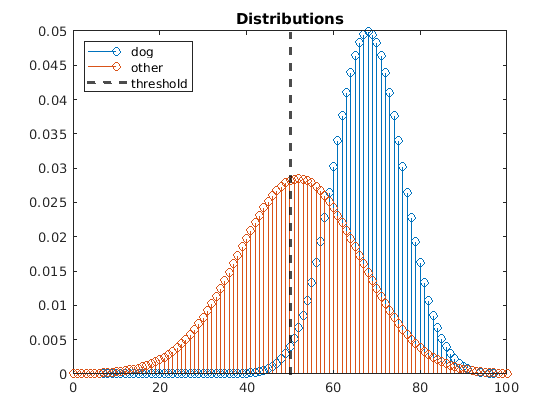

x = 0:100;
theshold = 50;
stem(x, dog.pdf(x))
hold on
stem(x, other.pdf(x))
title("Distributions")
xline(theshold, 'k--', 'LineWidth', 2)
legend( {'dog', 'other', 'threshold'}, 'Location', 'northwest')
hold off

% if FN had high cost, I would shift towards left
% so FP rate goes up, but FN rate goes down
% accuracy = (TP + TN) / (TP + TN + FP + FN)

tn = other.cdf(theshold);
fn = dog.cdf(theshold);
tp = 1 - dog.cdf(theshold);
fp = 1 - other.cdf(theshold);
accuracy = (tp + tn)/(tn + fn + tp + fp)

accuracy = 0.7155

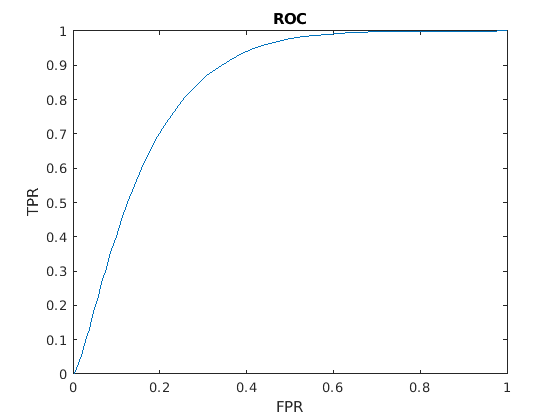


num_instances = 100;
TPR = ones(1, num_instances);
FPR = ones(1, num_instances);

for t = 1:num_instances
    tn = other.cdf(t);
    fn = dog.cdf(t);
    tp = 1 - dog.cdf(t);
    fp = 1 - other.cdf(t);
    TPR(t) = tp/(tp + fn);
    FPR(t) = fp/(tn + fp);
end

figure
plot(FPR, TPR)
hold on
title("ROC")
xlabel("FPR")
ylabel("TPR")
hold off

#### Conditions Where I Would Recommend Lie Detection In the Justice System

I would only recommend the use of lie detection in the justice system if it had perfect recall, perfect precision, and perfect accuracy. The main systemic issue I see is that people are ready to believe anything that claims to be more accurate than random chance. However, even a perfect system is wrong sometimes, and even if something is 99.99% accurate, that 0.01% error can drastically affect someone's life.

If hard-pressed to use such a technology in the justice system, I'd rather have a system with a lower false positive rate / low sensitivity / higher false negative rate, i.e.more likely to incorrectly say not lying, as a false positive has a higher cost: both in terms of harsher undeserved sentencing and the psycological effects of being wrongly called a liar.

This binary framing is somewhat lacking in terms of capturing the full dimension of lies. How do white lies or lies by omission or lies of willful ignorance get detected? Does a classifier have the option of answering "not sure" if it is not confident enough, and how does that multi-class behavior effect probabilities.

Also, food for thought, how does "innocent until proven guilty" factor into conditional probabilites?